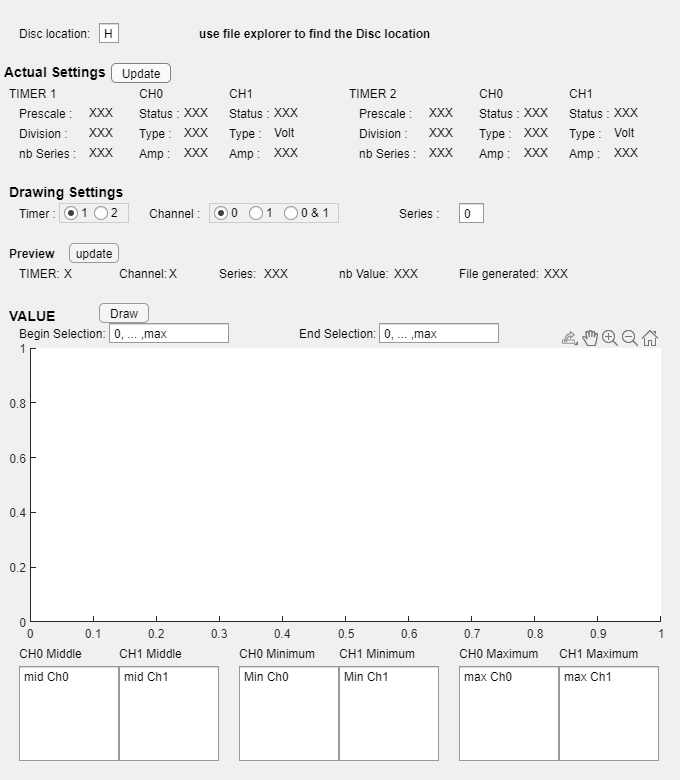

% Create figure window and components
clc
y = 780; x = 680;
x0 = 20;
x1 = 135;
x2 = 70;
x3 = 45;
pos = 20;

fig = uifigure('Position',[100 50 x y], ...
    'Name','DISPLAY DATA-Logger');
fig.Resize=0;

setappdata(fig, 'dl', 'H') ;

setappdata(fig, 'ft', "%s:%u_%u_Div%u.smp") ;
setappdata(fig, 'tm', 0);
setappdata(fig, 'ch', 0);
setappdata(fig, 'vr', 0);
setappdata(fig, 'nbData', 0);

% param

uilabel(fig, 'Position', [x0 y-pos*2 x1 15], 'Text','Disc location:');
discLoc = uitextarea(fig, 'Position',[100 y-pos*2-2 20 20],"Value",{'H'});
errorDL = uilabel(fig, 'Position', [200 y-pos*2 300 15], 'Text','use file explorer to find the Disc location',"FontWeight",'bold');

%affichage
uilabel(fig, 'Position', [5 y-pos*4 x1 18], 'Text','Actual Settings',"FontWeight",'bold',"FontSize",14);

%TM1
uilabel(fig, 'Position', [10 y-pos*5 x1 15], 'Text','TIMER 1');
uilabel(fig, 'Position', [x0 y-pos*6 x1 15], 'Text','Prescale :');
TM1P = uilabel(fig, 'Position', [x0+x2 y-pos*6-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*7 x1 15], 'Text','Division :');
TM1Div = uilabel(fig, 'Position', [x0+x2 y-pos*7-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [x0 y-pos*8 x1 15], 'Text','nb Series :');
TM1nbSeries = uilabel(fig, 'Position', [x0+x2 y-pos*8-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [140 y-pos*5 x1 15], 'Text','CH0');
uilabel(fig, 'Position', [140 y-pos*6 x1 15], 'Text','Status :');
TM1CH0use = uilabel(fig, 'Position', [140+x3 y-pos*6-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [140 y-pos*7 x1 15], 'Text','Type :');
TM1CH0VA = uilabel(fig, 'Position', [140+x3 y-pos*7-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [140 y-pos*8 x1 15], 'Text','Amp :');
TM1CH0Amp = uilabel(fig, 'Position', [140+x3 y-pos*8-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [140+90 y-pos*5 x1 15], 'Text','CH1');
uilabel(fig, 'Position', [140+90 y-pos*6 x1 15], 'Text','Status :');
TM1CH1use = uilabel(fig, 'Position', [140+x3+90 y-pos*6-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [140+90 y-pos*7 x1 15], 'Text','Type :');
uilabel(fig, 'Position', [140+x3+90 y-pos*7-2 130 20], 'Text','Volt');
uilabel(fig, 'Position', [140+90 y-pos*8 x1 15], 'Text','Amp :');
TM1CH1Amp = uilabel(fig, 'Position', [140+x3+90 y-pos*8-2 130 20], 'Text','XXX');

%TM2
uilabel(fig, 'Position', [340+10 y-pos*5 x1 15], 'Text','TIMER 2');
uilabel(fig, 'Position', [340+x0 y-pos*6 x1 15], 'Text','Prescale :');
TM2P = uilabel(fig, 'Position', [340+x0+x2 y-pos*6-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [340+x0 y-pos*7 x1 15], 'Text','Division :');
TM2Div = uilabel(fig, 'Position', [340+x0+x2 y-pos*7-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [340+x0 y-pos*8 x1 15], 'Text','nb Series :');
TM2nbSeries = uilabel(fig, 'Position', [340+x0+x2 y-pos*8-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [340+140 y-pos*5 x1 15], 'Text','CH0');
uilabel(fig, 'Position', [340+140 y-pos*6 x1 15], 'Text','Status :');
TM2CH0use = uilabel(fig, 'Position', [340+140+x3 y-pos*6-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [340+140 y-pos*7 x1 15], 'Text','Type :');
TM2CH0VA = uilabel(fig, 'Position', [340+140+x3 y-pos*7-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [340+140 y-pos*8 x1 15], 'Text','Amp :');
TM2CH0Amp = uilabel(fig, 'Position', [340+140+x3 y-pos*8-2 130 20], 'Text','XXX');

uilabel(fig, 'Position', [340+230 y-pos*5 x1 15], 'Text','CH1');
uilabel(fig, 'Position', [340+230 y-pos*6 x1 15], 'Text','Status :');
TM2CH1use = uilabel(fig, 'Position', [340+230+x3 y-pos*6-2 130 20], 'Text','XXX');
uilabel(fig, 'Position', [340+230 y-pos*7 x1 15], 'Text','Type :');
uilabel(fig, 'Position', [340+230+x3 y-pos*7-2 130 20], 'Text','Volt');
uilabel(fig, 'Position', [340+230 y-pos*8 x1 15], 'Text','Amp :');
TM2CH1Amp = uilabel(fig, 'Position', [340+230+x3 y-pos*8-2 130 20], 'Text','XXX');

uibutton(fig,'push', 'Position',[112 y-pos*4-2 60 20], 'Text', 'Update', 'ButtonPushedFcn', ...
    @(btn,event) updateGeneral(fig,discLoc.Value,TM1P,TM1Div,TM1nbSeries,TM1CH0use,TM1CH0VA,TM1CH0Amp,TM1CH1use,TM1CH1Amp,TM2P,TM2Div,TM2nbSeries,TM2CH0use,TM2CH0VA,TM2CH0Amp,TM2CH1use,TM2CH1Amp,errorDL));

% param
uilabel(fig, 'Position', [10 y-pos*10 x1 18], 'Text','Drawing Settings',"FontWeight",'bold',"FontSize",14);

uilabel(fig, 'Position', [x0 y-pos*11 x1 15], 'Text','Timer :');
bgTIMER = uibuttongroup(fig,'Position',[60 y-pos*11-2 70 20]);
rb1TIMER = uiradiobutton(bgTIMER,'Position',[5 0 30 20],"Text",'1');
rb2TIMER = uiradiobutton(bgTIMER,'Position',[35 0 30 20],"Text",'2');

uilabel(fig, 'Position', [150 y-pos*11 300 15], 'Text','Channel :');
bgCH = uibuttongroup(fig,'Position',[210 y-pos*11-2 130 20]);
rb1CH = uiradiobutton(bgCH,'Position',[5 0 50 20],"Text",'0');
rb2CH = uiradiobutton(bgCH,'Position',[40 0 50 20],"Text",'1');
rb3CH = uiradiobutton(bgCH,'Position',[75 0 70 20],"Text",'0 & 1');

uilabel(fig, 'Position', [400 y-pos*11 x1 15], 'Text','Series :');
seriesTextArea = uitextarea(fig, 'Position',[460 y-pos*11-2 25 20],"Value",{'0'});
errorFile = uilabel(fig, 'Position', [490 y-pos*11 200 15], 'Text','',"FontWeight",'bold',"FontColor",'#A2142F');

%info
uilabel(fig, 'Position', [10 y-pos*13 x1 15], 'Text','Preview',"FontWeight",'bold');

uilabel(fig, 'Position', [x0 y-pos*14 x1 15], 'Text','TIMER:');
timer = uilabel(fig, 'Position', [x0 + 45 y-pos*14 x1 15], 'Text','X');
uilabel(fig, 'Position', [120 y-pos*14 x1 15], 'Text','Channel:');
channel = uilabel(fig, 'Position', [120+50 y-pos*14 x1 15], 'Text','X');
uilabel(fig, 'Position', [220 y-pos*14 x1 15], 'Text','Series:');
series = uilabel(fig, 'Position', [220+45 y-pos*14 x1 15], 'Text','XXX');
uilabel(fig, 'Position', [340 y-pos*14 x1 15], 'Text','nb Value:');
nbVal = uilabel(fig, 'Position', [340+55 y-pos*14 x1 15], 'Text','XXX');
uilabel(fig, 'Position', [460 y-pos*14 x1 15], 'Text','File generated:');
fileGen = uilabel(fig, 'Position', [460+85 y-pos*14 x1 15], 'Text','XXX');

%value
uilabel(fig, 'Position', [10 y-pos*16 x1 15], 'Text','VALUE',"FontWeight",'bold',"FontSize",14);

uilabel(fig, 'Position', [x0 y-pos*17 x1 15], 'Text','Begin Selection:');
biginSectTextArea = uitextarea(fig, 'Position',[x0+90 y-pos*17-2 120 20],"Value",{'0, ... ,max'});

uilabel(fig, 'Position', [300 y-pos*17 x1 15], 'Text','End Selection:');
endSectTextArea = uitextarea(fig, 'Position',[300+80 y-pos*17-2 120 20],"Value",{'0, ... ,max'});

errorDraw = uilabel(fig, 'Position', [520 y-pos*17 x1 15], 'Text','',"FontWeight",'bold',"FontColor",'#A2142F');

ax = uiaxes('Parent',fig,...
    'Position', [10 y-pos*32 x-20 300]);

uilabel(fig, 'Position', [x0 y-pos*33 x1 15], 'Text','CH0 Middle');
valueMidTextAreaCh0 = uitextarea(fig, 'Position',[x0 y-pos*38 100 95],"Value",{'mid Ch0'});
uilabel(fig, 'Position', [x0+100 y-pos*33 x1 15], 'Text','CH1 Middle');
valueMidTextAreaCh1 = uitextarea(fig, 'Position',[x0+100 y-pos*38 100 95],"Value",{'mid Ch1'});
uilabel(fig, 'Position', [2*x0+200 y-pos*33 x1 15], 'Text','CH0 Minimum');
valueMinTextAreaCh0 = uitextarea(fig, 'Position',[2*x0+200 y-pos*38 100 95],"Value",{'Min Ch0'});
uilabel(fig, 'Position', [2*x0+300 y-pos*33 x1 15], 'Text','CH1 Minimum');
valueMinTextAreaCh1 = uitextarea(fig, 'Position',[2*x0+300 y-pos*38 100 95],"Value",{'Min Ch1'});
uilabel(fig, 'Position', [3*x0+400 y-pos*33 x1 15], 'Text','CH0 Maximum');
valueMaxTextAreaCh0 = uitextarea(fig, 'Position',[3*x0+400 y-pos*38 100 95],"Value",{'max Ch0'});
uilabel(fig, 'Position', [3*x0+500 y-pos*33 x1 15], 'Text','CH1 Maximum');
valueMaxTextAreaCh1 = uitextarea(fig, 'Position',[3*x0+500 y-pos*38 100 95],"Value",{'max Ch1'});

uibutton(fig,'push', 'Position',[70 y-pos*13-2 50 20], 'Text', 'update', 'ButtonPushedFcn', ...
    @(btn,event) update(fig,rb1TIMER.Value,rb1CH.Value,rb2CH.Value,seriesTextArea.Value,timer,channel,series,nbVal,fileGen,biginSectTextArea,endSectTextArea,errorFile));

uibutton(fig,'push', 'Position',[100 y-pos*16-2 50 20], 'Text', 'Draw', 'ButtonPushedFcn', ...
    @(btn,event) Draw(fig,biginSectTextArea.Value,endSectTextArea.Value,ax,valueMidTextAreaCh0,valueMidTextAreaCh1,valueMinTextAreaCh0,valueMinTextAreaCh1,valueMaxTextAreaCh0,valueMaxTextAreaCh1,errorDraw));

function updateGeneral(fig,discLoc,TM1P,TM1Div,TM1nbSeries,TM1CH0use,TM1CH0VA,TM1CH0Amp,TM1CH1use,TM1CH1Amp,TM2P,TM2Div,TM2nbSeries,TM2CH0use,TM2CH0VA,TM2CH0Amp,TM2CH1use,TM2CH1Amp,errorDL)
file = sprintf("%s:param.par",char(discLoc));
fid = fopen(file);
if(fid ~= -1)
    paramRX = fread(fid, inf, 'uint8');
    TM1P.Text=string(paramRX(1)+paramRX(2)*256*1+paramRX(3)*256*2+paramRX(4)*256*3);
    TM1Div.Text=string(2^paramRX(5));
    TM2P.Text=string(paramRX(6)+paramRX(7)*256*1);
    TM2Div.Text=string(2^paramRX(8));
    TM1nbSeries.Text = string(paramRX(10));
    if(paramRX(9)==0)
        TM1CH0use.Text = 'not use';
        TM1CH1use.Text = 'not use';
    elseif(paramRX(9)==1)
        TM1CH0use.Text = 'use';
        TM1CH1use.Text = 'not use';
    elseif(paramRX(9)==2)
        TM1CH0use.Text = 'use';
        TM1CH1use.Text = 'use';
    else
        TM1CH0use.Text = 'XX';
        TM1CH1use.Text = 'XX';
    end

    if(paramRX(11)== 1)
        TM1CH0VA.Text = 'volt';
    elseif(paramRX(11)== 0)
        TM1CH0VA.Text = 'amp';
    else
        TM1CH0VA.Text = 'XX';
    end

    if(paramRX(12)==0)
        TM1CH0Amp.Text = '*1';
    elseif(paramRX(12)==1)
        TM1CH0Amp.Text = '*10';
    elseif(paramRX(12)==2)
        TM1CH0Amp.Text = '*50';
    else
        TM1CH0Amp.Text = 'XX';
    end
    if(paramRX(13)==0)
        TM1CH1Amp.Text = '*1';
    elseif(paramRX(13)==1)
        TM1CH1Amp.Text = '*10';
    elseif(paramRX(13)==2)
        TM1CH1Amp.Text = '*50';
    else
        TM1CH1Amp.Text = 'XX';
    end

    TM2nbSeries.Text = string(paramRX(15));
    if(paramRX(14)==0)
        TM2CH0use.Text = 'not use';
        TM2CH1use.Text = 'not use';
    elseif(paramRX(14)==1)
        TM2CH0use.Text = 'use';
        TM2CH1use.Text = 'not use';
    elseif(paramRX(14)==2)
        TM2CH0use.Text = 'use';
        TM2CH1use.Text = 'use';
    else
        TM2CH0use.Text = 'XX';
        TM2CH1use.Text = 'XX';
    end

    if(paramRX(16)== 1)
        TM2CH0VA.Text = 'volt';
    elseif(paramRX(16)== 0)
        TM2CH0VA.Text = 'amp';
    else
        TM2CH0VA.Text = 'XX';
    end

    if(paramRX(17)==0)
        TM2CH0Amp.Text = '*1';
    elseif(paramRX(17)==1)
        TM2CH0Amp.Text = '*10';
    elseif(paramRX(17)==2)
        TM2CH0Amp.Text = '*50';
    else
        TM2CH0Amp.Text = 'XX';
    end
    if(paramRX(18)==0)
        TM2CH1Amp.Text = '*1';
    elseif(paramRX(18)==1)
        TM2CH1Amp.Text = '*10';
    elseif(paramRX(18)==2)
        TM2CH1Amp.Text = '*50';
    else
        TM2CH1Amp.Text = 'XX';
    end

    fclose(fid);
    setappdata(fig, 'dl' ,discLoc);
    errorDL.Text = "";
else
    errorDL.Text = "error : Disc Location NOK";
    errorDL.FontColor='#A2142F';
end
end

function update(fig,rb1TIMER,rb1CH,rb2CH,seriesTextArea,timer,channel,serie,nbVal,fileGen,biginSectTextArea,endSectTextArea,errorFile)
if(rb1TIMER)
    tm = 0;
    timer.Text = "1";
else
    tm = 1;
    timer.Text = "2";
end

setappdata(fig,'tm',tm);
if(rb1CH)
    channel.Text = "0";
    ch=0;
elseif(rb2CH)
    channel.Text = "1";
    ch=1;
else
    channel.Text = "0 & 1";
    ch=2;
end
setappdata(fig,'ch',ch);

series = str2double(string(seriesTextArea));
if( ~isnan(series))
    serie.Text = string(seriesTextArea);
    series = str2double(string(seriesTextArea));
    setappdata(fig,'vr',series);
    genFile(fig,nbVal,fileGen,biginSectTextArea,endSectTextArea,errorFile);
else
    errorFile.Text = "error: series is not a number";
end

end

function genFile(fig,nbVal,fileGen,biginSectTextArea,endSectTextArea,errorFile)

discLoc = getappdata(fig,'dl');
fileText = getappdata(fig,'ft');
timer = getappdata(fig,'tm');
series = getappdata(fig,'vr');
channel = getappdata(fig,'ch');

file0 = sprintf(fileText,char(discLoc),timer,series,0);
fid0 = fopen(file0);

if(fid0>0)
    fseek(fid0,-4,"eof");
    nbValueF0 = ftell(fid0)/2;

    fseek(fid0,0,"bof");
    RX_Data_0 = fread(fid0,4,"uint8");

    if(RX_Data_0(1)==2)
        nbValueF0=nbValueF0/2;
    end

    nbv=nbValueF0;
    if(nbv>1000)
        nbv= nbv/1000;
        if(nbv>1000)
            nbv= nbv/1000;
            nbVal.Text = sprintf("%.3g M",nbv);
        else
            nbVal.Text = sprintf("%.3g K",nbv);
        end
    else
        nbVal.Text = sprintf("%u",nbv);
    end
    biginSectTextArea.Value = "0";
    endSectTextArea.Value = sprintf("%u", nbValueF0);
    setappdata(fig,'nbData',nbValueF0);



    %test file gen
    file1 = sprintf(fileText,char(discLoc),timer,series,1);
    fid1 = fopen(file1);

    if(fid1 == -1)
        if((RX_Data_0(1) == 1) && (channel == 0))
            fileGen.Text="0%";
            lod10 = floor(nbValueF0/20000);
            nbLod = 1;

            fid1 = fopen(file1,'w+');
            %write param data
            fwrite(fid1,RX_Data_0,"uint8");

            value = zeros(1,60,'uint16');
            for x = 0:1:(nbValueF0/2000)-1
                RX_Data_0 = fread(fid0,2000,"uint16");
                for y = 0:1:19
                    midVal = 0;
                    min = RX_Data_0(1+y*100);
                    max = 0;
                    for z = 1:100
                        data = RX_Data_0(y*100+z);
                        if(data<min)
                            min=data;
                        end
                        if(data>max)
                            max=data;
                        end
                        midVal = midVal + data;
                    end
                    value(1+y*3) = min;
                    value(2+y*3) = midVal/100;
                    value(3+y*3) = max;
                end
                fwrite(fid1,value,"uint16");
                if(x>=lod10*nbLod)
                    nbLod =nbLod+1;
                    fileGen.Text=sprintf("%u %",nbLod*10);
                end
            end
            %div2 gen
            fid2 = gen1ChSubDiv(fig,fid1,2);
            if (fid2)
                %div3 gen
                fid3 = gen1ChSubDiv(fig,fid2,3);
                if(fid3)
                    fclose(fid3);
                end
                fclose(fid2);
            end
            fclose(fid1);
            fileGen.Text="100%";
            errorFile.Text = "";

        elseif(RX_Data_0(1)  == 2)
            fileGen.Text="0%";
            lod10 = floor(nbValueF0/10000);
            nbLod = 1;
            fid1 = fopen(file1,'w+');
            %write param data
            fwrite(fid1,RX_Data_0,"uint8");

            value = zeros(1,60,'uint16');
            for x = 0:1:(nbValueF0/1000)-1
                RX_Data_0 = fread(fid0,2000,"uint16");
                for y = 0:1:9
                    midVal1 = 0;
                    min1 = RX_Data_0(1+y*200);
                    max1 = 0;
                    midVal2 = 0;
                    min2 = RX_Data_0(4+y*200);
                    max2 = 0;

                    for z = 1:100
                        data1 = RX_Data_0(y*200+z*2-1);
                        if(data1<min1)
                            min1=data1;
                        end
                        midVal1 = midVal1 + data1;
                        if(data1>max1)
                            max1=data1;
                        end

                        data2 = RX_Data_0(y*200+z*2);
                        if(data2<min2)
                            min2=data2;
                        end
                        midVal2 = midVal2 + data2;
                        if(data2>max2)
                            max2=data2;
                        end

                    end
                    value(1+y*6) = min1;
                    value(2+y*6) = midVal1/100;
                    value(3+y*6) = max1;
                    value(4+y*6) = min2;
                    value(5+y*6) = midVal2/100;
                    value(6+y*6) = max2;
                end
                fwrite(fid1,value,"uint16");
                if(x>=lod10*nbLod)
                    nbLod =nbLod+1;
                    fileGen.Text=sprintf("%u %",nbLod*10);
                end
            end

            %div2 gen
            fid2 = gen2ChSubDiv(fig,fid1,2);
            if (fid2)
                %div3 gen
                fid3 = gen2ChSubDiv(fig,fid2,3);
                if(fid3)
                    fclose(fid3);
                end
                fclose(fid2);
            end
            fclose(fid1);
            fileGen.Text="100%";
            errorFile.Text = "";
        else
            fileGen.Text="File NOK";
            errorFile.Text = "error: please use CH0";
        end
    else
        fseek(fid0,0,"bof");
        RX_Data_0 = fread(fid0,4,"uint8");
        if(((RX_Data_0(1) == 1) && (channel == 0)) || (RX_Data_0(1) == 2))
            fileGen.Text="File Ok";
            errorFile.Text = "";
        else
            fileGen.Text="File NOK";
            errorFile.Text = "error: please use CH0";
        end

    end
    fclose(fid0);
else
    nbVal.Text = "XXX";
    fileGen.Text="File NOK";
    errorFile.Text = "error: please use valid settings";
end
end

function fidDown = gen1ChSubDiv(fig,fid,divDown)

discLoc = getappdata(fig,'dl');
fileText = getappdata(fig,'ft');
timer = getappdata(fig,'tm');
series = getappdata(fig,'vr');

fseek(fid,-4,"eof");
nbValue = ftell(fid)/(2*3); %2*->uint16 , 3* -> 3 value/mesure
if(nbValue >= 10000) %gen si plus de 100 valeur a y mettre
    fseek(fid,0,"bof");
    RX_Data = fread(fid,4,"uint8");
    fileDown = sprintf(fileText,char(discLoc),timer,series,divDown);
    fidDown = fopen(fileDown,'w+');
    fwrite(fidDown,RX_Data,"uint8");
    fseek(fid,4,"bof");
    while (nbValue>100)
        RX_Data = fread(fid,300,"uint16");
        valueF=[RX_Data(1),0,0];
        midVal = 0;

        for x = 0:99
            if( RX_Data(1+3*x)<valueF(1))
                valueF(1)= RX_Data(1+3*x);
            end

            midVal = midVal + RX_Data(2+3*x);

            if(RX_Data(2+3*x)>valueF(3))
                valueF(3)=RX_Data(3+3*x);
            end
        end
        valueF(2) = midVal/100;

        fwrite(fidDown,valueF,"uint16");
        nbValue = nbValue-100;
    end

    RX_Data = fread(fid,3*nbValue,"uint16");
    valueF=[0,0,0];
    midVal = 0;

    for x = 0:nbValue-1
        if( RX_Data(1+3*x)<valueF(1))
            valueF(1)= RX_Data(1+3*x);
        end
        if(RX_Data(2+3*x)>valueF(3))
            valueF(3)=RX_Data(2+3*x);
        end
        midVal = midVal + RX_Data(3+3*x);
    end
    valueF(2) = midVal/nbValue;

    fwrite(fidDown,valueF,"uint16");
else
    fidDown = 0;
end
end

function fidDown = gen2ChSubDiv(fig,fid,divDown)

discLoc = getappdata(fig,'dl');
fileText = getappdata(fig,'ft');
timer = getappdata(fig,'tm');
series = getappdata(fig,'vr');

fseek(fid,-4,"eof");
nbValue = ftell(fid)/(2*3*2); %2*->uint16 , 3* -> 3 value/mesure , 2* -> 2CH
if(nbValue >= 10000) %gen si plus de 100 valeur a y mettre
    fseek(fid,0,"bof");
    RX_Data = fread(fid,4,"uint8");
    fileDown = sprintf(fileText,char(discLoc),timer,series,divDown);
    fidDown = fopen(fileDown,'w+');
    fwrite(fidDown,RX_Data,"uint8");
    fseek(fid,4,"bof");
    while (nbValue>100)
        RX_Data = fread(fid,600,"uint16");
        valueF=[RX_Data(1),0,0,RX_Data(4),0,0];
        midVal1 = 0;
        midVal2 = 0;

        for x = 0:99
            if( RX_Data(1+6*x)<valueF(1))
                valueF(1)= RX_Data(1+6*x);
            end
            midVal1 = midVal1 + RX_Data(2+6*x);
            if(RX_Data(3+6*x)>valueF(3))
                valueF(3)=RX_Data(3+6*x);
            end

            if( RX_Data(4+6*x)<valueF(4))
                valueF(1)= RX_Data(4+6*x);
            end
            midVal2 = midVal2 + RX_Data(5+6*x);
            if(RX_Data(6+6*x)>valueF(6))
                valueF(6)=RX_Data(6+6*x);
            end
        end
        valueF(2) = midVal1/100;
        valueF(5) = midVal2/100;

        fwrite(fidDown,valueF,"uint16");
        nbValue = nbValue-100;
    end

    RX_Data = fread(fid,6*nbValue,"uint16");
    valueF=[0,0,0,0,0,0];
    midVal1 = 0;
    midVal2 = 0;

    for x = 0:nbValue-1
        if( RX_Data(1+6*x)<valueF(1))
            valueF(1)= RX_Data(1+6*x);
        end
        midVal1 = midVal1 + RX_Data(2+6*x);
        if(RX_Data(3+6*x)>valueF(3))
            valueF(3)=RX_Data(3+6*x);
        end

        if( RX_Data(4+6*x)<valueF(4))
            valueF(1)= RX_Data(4+6*x);
        end
        midVal2 = midVal2 + RX_Data(5+6*x);
        if(RX_Data(6+6*x)>valueF(6))
            valueF(6)=RX_Data(6+6*x);
        end
    end
    valueF(2) = midVal1/100;
    valueF(5) = midVal2/100;
    fwrite(fidDown,valueF,"uint16");
else
    fidDown = 0;
end
end

function Draw(fig,biginSectTextArea,endSectTextArea,ax,valueMidTextAreaCh0,valueMidTextAreaCh1,valueMinTextAreaCh0,valueMinTextAreaCh1,valueMaxTextAreaCh0,valueMaxTextAreaCh1,errorDraw)
discLoc = getappdata(fig,'dl');
fileText = getappdata(fig,'ft');
timer = getappdata(fig,'tm');
series= getappdata(fig,'vr');
channel = getappdata(fig,'ch');
nbData = getappdata(fig,'nbData');
sizeChange = 100;

beginSel = str2double(biginSectTextArea);
endSel = str2double(endSectTextArea);
sizeSel = endSel-beginSel+1;


if ((beginSel<endSel) && endSel<=nbData)
    errorDraw.Text = "";
    %chose div
    if(sizeSel>=sizeChange*100^1)
        if(sizeSel>=sizeChange*100^2)
            if(sizeSel>=sizeChange*100^3)
                div=3;
            else
                div=2;
            end
        else
            div=1;
        end
    else
        div=0;
    end

    file = sprintf(fileText,char(discLoc),timer,series,div);
    fid = fopen(file,'r');
    fseek(fid,0,"bof");
    dataParam = fread(fid,4,"uint8");

    if((dataParam(1)==1) && (channel==0))
        size = floor(sizeSel/100^div);
        mid = zeros(1,size);
        x=floor(beginSel/100^div)*100^div:100^div:beginSel-1 + size*100^div;

        if(div~=0)
            neg = zeros(1,size);
            pos = zeros(1,size);
            fseek(fid,4+(floor(beginSel/100^div)*6),"bof");
            data = fread(fid,size*3,"uint16");
            for z=0:1:size-1
                mid(z+1)=data(2+3*z);
                neg(z+1)=data(2+3*z)-data(1+3*z);
                pos(z+1)=data(3+3*z)-data(2+3*z);
            end

            %add modif value
            if(dataParam(2)==0) %ampere
                if(dataParam(3)==2)%*50
                    leg = 'ch0: A_*50';
                    mid = ((mid/(2^16*50)));
                    neg = ((neg/(2^16*50)));
                    pos = ((pos/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg = 'ch0: A_*10';
                    mid = ((mid/(2^16*10)));
                    neg = ((neg/(2^16*10)));
                    pos = ((pos/(2^16*10)));
                else%*1
                    leg = 'ch0: A_*1';
                    mid = ((mid/2^16));
                    neg = ((neg/2^16));
                    pos = ((pos/2^16));
                end
            else %volt
                if(dataParam(3)==2)%*50
                    leg = 'ch0: V_*50';
                    mid = ((mid*28/(2^16*50)));
                    neg = ((neg*28/(2^16*50)));
                    pos = ((pos*28/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg = 'ch0: V_*10';
                    mid = ((mid*28/(2^16*10)));
                    neg = ((neg*28/(2^16*10)));
                    pos = ((pos*28/(2^16*10)));
                else%*1
                    leg = 'ch0: V_*1';
                    mid = ((mid*28/2^16));
                    neg = ((neg*28/2^16));
                    pos = ((pos*28/2^16));
                end
            end

            errorbar(ax,x,mid,neg,pos,'Color', 'r');
            legend(ax,leg);
            valueMidTextAreaCh0.Value = string(mid);
            valueMinTextAreaCh0.Value = string(neg);
            valueMaxTextAreaCh0.Value = string(pos);

        else
            fseek(fid,4+(beginSel*2),"bof");
            data = fread(fid,size,"uint16");
            for z=1:size
                mid(z)=data(z);
            end

            %add modif value
            if(dataParam(2)==0) %ampere
                if(dataParam(3)==2)%*50
                    leg = 'ch0: A_*50';
                    mid = ((mid/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg = 'ch0: A_*10';
                    mid = ((mid/(2^16*10)));
                else%*1
                    leg = 'ch0: A_*1';
                    mid = ((mid/2^16));
                end
            else %volt
                if(dataParam(3)==2)%*50
                    leg = 'ch0: V_*50';
                    mid = ((mid*28/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg = 'ch0: V_*10';
                    mid = ((mid*28/(2^16*10)));
                else%*1
                    leg = 'ch0: V_*1';
                    mid = ((mid*28/2^16));
                end
            end


            plot(ax,x,mid,'Color', 'r');
            legend(ax,leg);
            valueMidTextAreaCh0.Value = string(mid);
            valueMinTextAreaCh0.Value = "no value";
            valueMaxTextAreaCh0.Value = "no value";
        end

    elseif (dataParam(1)==2)
        size = floor(sizeSel/100^div);
        x=floor(beginSel/100^div)*100^div:100^div:beginSel-1 + size*100^div;
        if(channel==0)
            mid = zeros(1,size);
            if(div~=0)
                neg = zeros(1,size);
                pos = zeros(1,size);
                fseek(fid,4+(floor(beginSel/100^div)*12),"bof");
                data = fread(fid,size*6,"uint16");
                for z=0:1:size-1
                    mid(z+1)=data(2+6*z);
                    neg(z+1)=data(2+6*z)-data(1+6*z);
                    pos(z+1)=data(3+6*z)-data(2+6*z);
                end

                %add modif value
                if(dataParam(2)==0) %ampere
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: A_*50';
                        mid = ((mid/(2^16*50)));
                        neg = ((neg/(2^16*50)));
                        pos = ((pos/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: A_*10';
                        mid = ((mid/(2^16*10)));
                        neg = ((neg/(2^16*10)));
                        pos = ((pos/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: A_*1';
                        mid = ((mid/2^16));
                        neg = ((neg/2^16));
                        pos = ((pos/2^16));
                    end
                else %volt
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: V_*50';
                        mid = ((mid*28/(2^16*50)));
                        neg = ((neg*28/(2^16*50)));
                        pos = ((pos*28/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: V_*10';
                        mid = ((mid*28/(2^16*10)));
                        neg = ((neg*28/(2^16*10)));
                        pos = ((pos*28/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: V_*1';
                        mid = ((mid*28/2^16));
                        neg = ((neg*28/2^16));
                        pos = ((pos*28/2^16));
                    end
                end


                errorbar(ax,x,mid,neg,pos,'Color', 'r');
                legend(ax,leg1);
                valueMidTextAreaCh0.Value = string(mid);
                valueMinTextAreaCh0.Value = string(neg);
                valueMaxTextAreaCh0.Value = string(pos);

            else
                fseek(fid,4+(floor(beginSel)*4),"bof");
                data = fread(fid,size*2,"uint16");
                for z=1:size
                    mid(z)=data(z*2-1);
                end

                %add modif value
                if(dataParam(2)==0) %ampere
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: A_*50';
                        mid = ((mid/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: A_*10';
                        mid = ((mid/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: A_*1';
                        mid = ((mid/2^16));
                    end
                else %volt
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: V_*50';
                        mid = ((mid*28/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: V_*10';
                        mid = ((mid*28/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: V_*1';
                        mid = ((mid*28/2^16));
                    end
                end
                plot(ax,x,mid,'Color', 'r');
                legend(ax,leg1);
                valueMidTextAreaCh0.Value = string(mid);
                valueMinTextAreaCh0.Value = "no value";
                valueMaxTextAreaCh0.Value = "no value";
            end

        elseif(channel==1)
            mid = zeros(1,size);
            if(div~=0)
                neg = zeros(1,size);
                pos = zeros(1,size);
                fseek(fid,4+(floor(beginSel/100^div)*12),"bof");
                data = fread(fid,size*6,"uint16");
                for z=0:1:size-1
                    mid(z+1)=data(5+6*z);
                    neg(z+1)=data(5+6*z)-data(4+6*z);
                    pos(z+1)=data(6+6*z)-data(5+6*z);
                end

                %add modif value
                %volt
                if(dataParam(3)==2)%*50
                    leg2 = 'ch1: V_*50';
                    mid = ((mid*28/(2^16*50)));
                    neg = ((neg*28/(2^16*50)));
                    pos = ((pos*28/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg2 = 'ch1: V_*10';
                    mid = ((mid*28/(2^16*10)));
                    neg = ((neg*28/(2^16*10)));
                    pos = ((pos*28/(2^16*10)));
                else%*1
                    leg2 = 'ch1: V_*1';
                    mid = ((mid*28/2^16));
                    neg = ((neg*28/2^16));
                    pos = ((pos*28/2^16));
                end

                errorbar(ax,x,mid,neg,pos,'Color', 'b');
                legend(ax,leg2);
                valueMidTextAreaCh1.Value = string(mid);
                valueMinTextAreaCh1.Value = string(neg);
                valueMaxTextAreaCh1.Value = string(pos);

            else
                fseek(fid,4+(floor(beginSel)*4),"bof");
                data = fread(fid,size*2,"uint16");
                for z=1:size
                    mid(z)=data(z*2);
                end

                %add modif value
                %volt
                if(dataParam(4)==2)%*50
                    leg2 = 'ch1: V_*50';
                    mid = ((mid*28/(2^16*50)));
                elseif(dataParam(4)==1)%*10
                    leg2 = 'ch1: V_*10';
                    mid = ((mid*28/(2^16*10)));
                else%*1
                    leg2 = 'ch1: V_*1';
                    mid = ((mid*28/2^16));
                end

                plot(ax,x,mid,'Color', 'b');
                legend(ax,leg2);

                valueMidTextAreaCh1.Value = string(mid);
                valueMinTextAreaCh1.Value = "no value";
                valueMaxTextAreaCh1.Value = "no value";
            end
        elseif (channel == 2)
            mid1 = zeros(1,size);
            mid2 = zeros(1,size);
            if(div~=0)
                neg1 = zeros(1,size);
                pos1 = zeros(1,size);
                neg2 = zeros(1,size);
                pos2 = zeros(1,size);
                fseek(fid,4+(floor(beginSel/100^div)*12),"bof");
                data = fread(fid,size*6,"uint16");
                for z=0:1:size-1
                    mid1(z+1)=data(2+6*z);
                    neg1(z+1)=data(2+6*z)-data(1+6*z);
                    pos1(z+1)=data(3+6*z)-data(2+6*z);
                    mid2(z+1)=data(5+6*z);
                    neg2(z+1)=data(5+6*z)-data(4+6*z);
                    pos2(z+1)=data(6+6*z)-data(5+6*z);
                end

                %add modif value
                if(dataParam(2)==0) %ampere
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: A_*50';
                        mid1 = ((mid1/(2^16*50)));
                        neg1 = ((neg1/(2^16*50)));
                        pos1 = ((pos1/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: A_*10';
                        mid1 = ((mid1/(2^16*10)));
                        neg1 = ((neg1/(2^16*10)));
                        pos1 = ((pos1/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: A_*1';
                        mid1 = ((mid1/2^16));
                        neg1 = ((neg1/2^16));
                        pos1 = ((pos1/2^16));
                    end
                else %volt
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: V_*50';
                        mid1 = ((mid1*28/(2^16*50)));
                        neg1 = ((neg1*28/(2^16*50)));
                        pos1 = ((pos1*28/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: V_*10';
                        mid1 = ((mid1*28/(2^16*10)));
                        neg1 = ((neg1*28/(2^16*10)));
                        pos1 = ((pos1*28/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: V_*1';
                        mid1 = ((mid1*28/2^16));
                        neg1 = ((neg1*28/2^16));
                        pos1 = ((pos1*28/2^16));
                    end
                end

                %add modif value CH1
                %volt
                if(dataParam(3)==2)%*50
                    leg2 = 'ch1: V_*50';
                    mid2 = ((mid2*28/(2^16*50)));
                    neg2 = ((neg2*28/(2^16*50)));
                    pos2 = ((pos2*28/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg2 = 'ch1: V_*10';
                    mid2 = ((mid2*28/(2^16*10)));
                    neg2 = ((neg2*28/(2^16*10)));
                    pos2 = ((pos2*28/(2^16*10)));
                else%*1
                    leg2 = 'ch1: V_*1';
                    mid2 = ((mid2*28/2^16));
                    neg2 = ((neg2*28/2^16));
                    pos2 = ((pos2*28/2^16));
                end


                errorbar(ax,x,mid1,neg1,pos1,'Color', 'r');
                hold (ax,'on');
                errorbar(ax,x,mid2,neg2,pos2,'Color', 'b');
                legend(ax,leg1,leg2);
                hold (ax,'off');

                valueMidTextAreaCh0.Value = string(mid1);
                valueMidTextAreaCh1.Value = string(mid2);
                valueMinTextAreaCh0.Value = string(neg1);
                valueMinTextAreaCh1.Value = string(neg2);
                valueMaxTextAreaCh0.Value = string(pos1);
                valueMaxTextAreaCh1.Value = string(pos2);

            else
                fseek(fid,4+(floor(beginSel)*4),"bof");
                data = fread(fid,size*2,"uint16");
                for z=1:size
                    mid1(z)=data(z*2-1);
                    mid2(z)=data(z*2);
                end

                %add modif value
                if(dataParam(2)==0) %ampere
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: A_*50';
                        mid1 = ((mid1/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: A_*10';
                        mid1 = ((mid1/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: A_*1';
                        mid1 = ((mid1/2^16));
                    end
                else %volt
                    if(dataParam(3)==2)%*50
                        leg1 = 'ch0: V_*50';
                        mid1 = ((mid1*28/(2^16*50)));
                    elseif(dataParam(3)==1)%*10
                        leg1 = 'ch0: V_*10';
                        mid1 = ((mid1*28/(2^16*10)));
                    else%*1
                        leg1 = 'ch0: V_*1';
                        mid1 = ((mid1*28/2^16));
                    end
                end

                %add modif value CH1
                %volt
                if(dataParam(3)==2)%*50
                    leg2 = 'ch1: V_*50';
                    mid2 = ((mid2*28/(2^16*50)));
                elseif(dataParam(3)==1)%*10
                    leg2 = 'ch1: V_*10';
                    mid2 = ((mid2*28/(2^16*10)));
                else%*1
                    leg2 = 'ch1: V_*1';
                    mid2 = ((mid2*28/2^16));
                end


                plot(ax,x,mid1,'Color','r');
                hold (ax,'on');
                plot(ax,x,mid2,'Color','b');
                legend(ax,leg1,leg2);
                hold (ax,'off');

                valueMidTextAreaCh0.Value = string(mid1);
                valueMidTextAreaCh1.Value = string(mid2);
                valueMinTextAreaCh0.Value = "no value";
                valueMinTextAreaCh1.Value = "no value";
                valueMaxTextAreaCh0.Value = "no value";
                valueMaxTextAreaCh1.Value = "no value";
            end
        end
    end
else
    errorDraw.Text = "error : check the selection Settings";
end
end